%% 求解解析解:
clear;clc
% close all

%% 求解Malthus模型
% 直接使用dsolve()进行求解
x = dsolve("Dx=r*x", "x(0)=x0", "t")

$$x = x_{0}\,{\mathrm{e}}^{r\,t}$$

% 使用Matlab推荐的写法:
syms x(t) t r; % r也要加上
equ = (diff(x,t) == r*x)

$$equ(t) = \frac{\partial }{\partial t}x\left(t\right)=r\,x\left(t\right)$$

x = dsolve(equ, 'x(0)=x0', 't')

$$x = x_{0}\,{\mathrm{e}}^{r\,t}$$

% 得到结果后, 我发现里面有两个未知量, 分别是x0(初始值), r(增长率)
% 于是我们先对进行复制
x0 = 100; % 初始的人口数
r = 0.1; % 人口增长率
x = subs(x) % 替换, 就是将里面的未知量, 替换成工作区同名的变量

$$x = 100\,{\mathrm{e}}^{t/10}$$

% 这样就将x被替换了.

x = dsolve("Dx=r*x", "x(0)=x0", "t")

$$x = x_{0}\,{\mathrm{e}}^{r\,t}$$

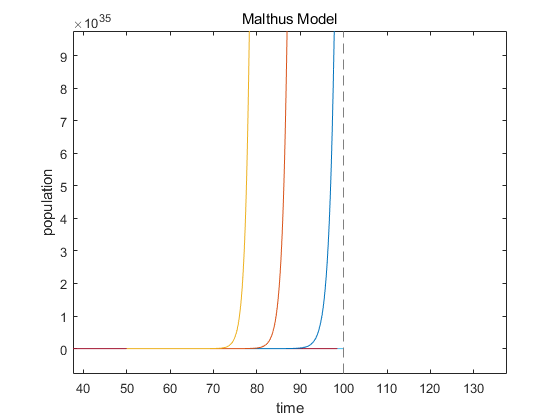

% 画出图形
% 初始人口为1000，画出50年且增长率分别为0.5%，1%，1.5% 一直到5%的人口变化曲线
figure(1);
x0 = 1000;
r = 0.005;
for i = 1: 10
    r = 0.005 * i;
    current_x = subs(x);
    fplot(current_x, [0, 50]); % 画出图像, 并且设置level
    
    hold on;
end
title("Malthus Model");
xlabel("time"); ylabel("population");

%% 求解logistic模型(阻滞增长模型)
clear; clc
% 求解:
x = dsolve("Dx=r*(1-x/x_m)*x", "x(t_0)=x_0", "t")

$$x = -\frac{x_{m}}{{\mathrm{e}}^{\log\left(1-\frac{x_{m}}{x_{0}}\right)-r\,t+r\,t_{0}}-1}$$

x = simplify(x)

$$x = \frac{x_{0}\,x_{m}\,{\mathrm{e}}^{r\,\left(t-t_{0}\right)}}{x_{m}-x_{0}+x_{0}\,{\mathrm{e}}^{r\,\left(t-t_{0}\right)}}$$

% 观察方程的变量值
% 定义变量:
t_0 = 0; % 初始
x_0 = 1000; % 初始的人数
x_m = 10000; % 人数最大
r = 0.05;
% 替换:
subs_x = subs(x);
subs_x

$$subs\_x = \frac{10000000\,{\mathrm{e}}^{t/20}}{1000\,{\mathrm{e}}^{t/20}+9000}$$

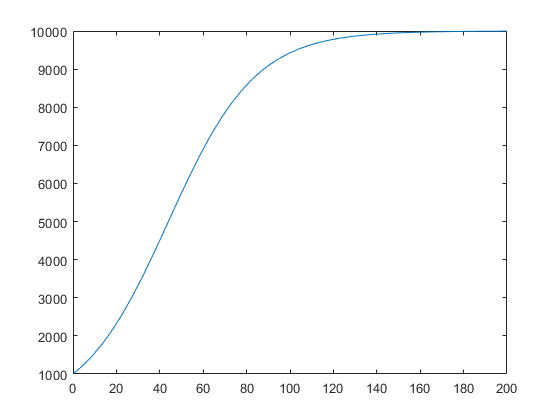

figure(2)
fplot(subs_x, [0, 200]);

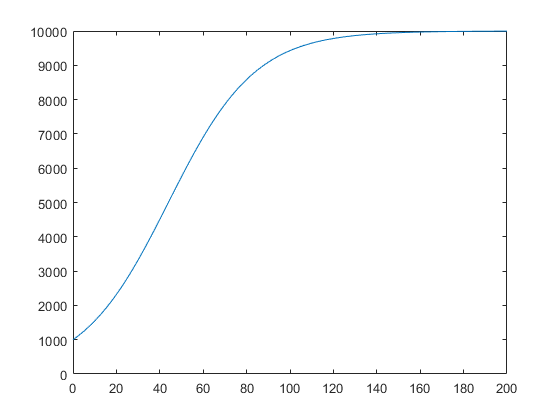

% 当然你也可以使用传统的plot, 使用向量方式进行画图
t = 0:200;
x = 10000 ./ (exp(log(9) - t/20) + 1);
plot(t,x,'-')